# **Practice with Vectors**

So far, you've learned some fundamental operations to create and work with vectors. In this live script, you'll review earlier concepts and learn new vector operations. The activities are divided into the following sections:

## Creating Vectors

There are many ways to create vectors. In this section, you will see how to 

- Create vectors using concatenation.

- Create vectors with a set spacing.

- Create vectors with a set number of elements.

### Concatenation

Square brackets are used to group elements together into vectors. Use a space between elements to create a row vector, or add a semicolon between elements to create a column vector.

             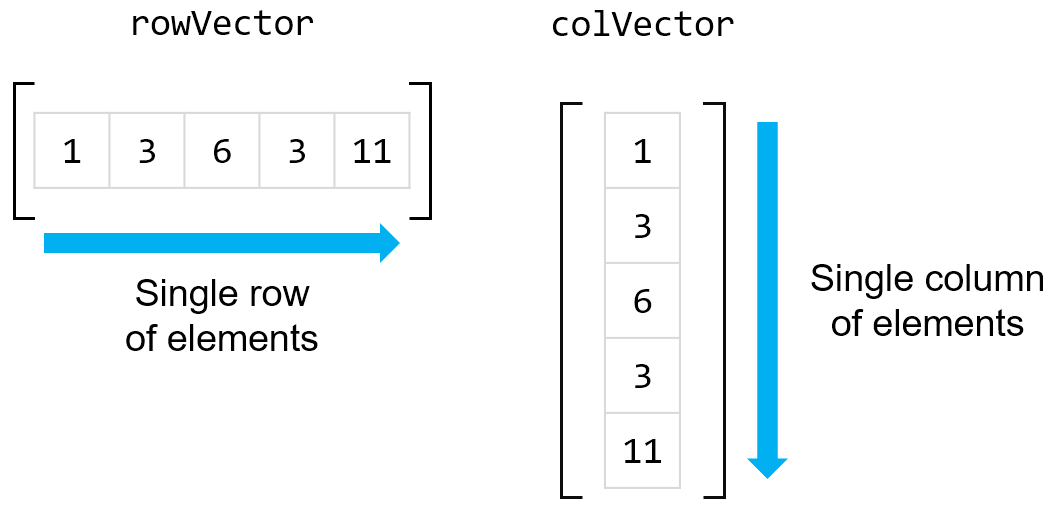

Use concatenation to create a column vector v`1` with the following elements: 0, 1, 1, 0.

v1 = [0;1;1;0]

v1 =      0
     1
     1
     0


Create a second column vector `v2` with the following elements: 0,5,0.

v2 = [0;5;0]

v2 =      0
     5
     0


Square brackets are also used to combine vectors together. Create a new column vector `v3` that combines the `v1` and `v2` vectors together. This should create a new column vector with seven rows and one column.

v3 = [v1;v2]

v3 =      0
     1
     1
     0
     0
     5
     0


### Vectors with Set Spacing

The [colon](https://www.mathworks.com/help/matlab/ref/colon.html) operator creates a row vector with a set spacing. If you do not specify the spacing value, it will use a default spacing of 1.

            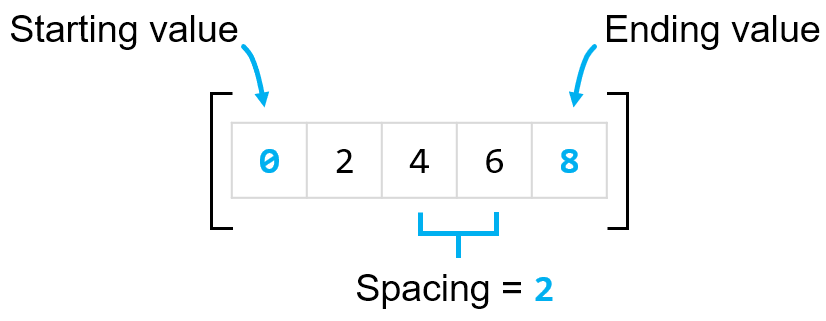

Use the colon operator to create a vector named v4 that starts at 45, ends at 90, with a spacing of 5.

v4 = 45:5:90

v4 =     45    50    55    60    65    70    75    80    85    90


Use the colon operator to create a vector named `v5` that starts at -10 and ends at 5, with the default spacing of 1.

v5 = -10:5

v5 =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5


### Vectors with Set Number of Elements

The [`linspace`](https://www.mathworks.com/help/matlab/ref/linspace.html) function creates a vector with a set number of equally spaced elements:

            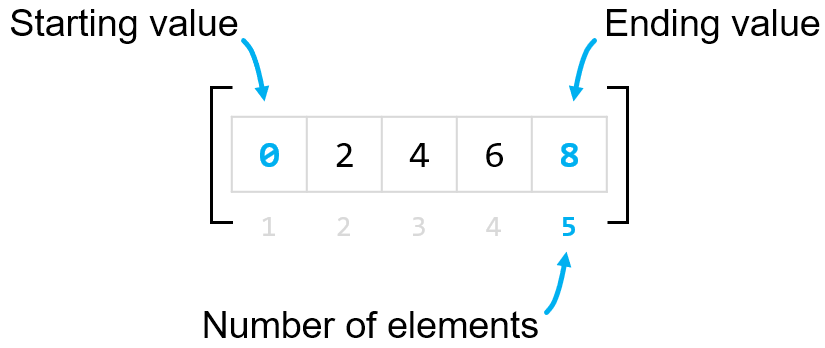

Use the `linspace` function to create a vector named v6 that starts at 0, ends at $2\pi$, with 5 equally spaced elements. Use the [`pi`](https://www.mathworks.com/help/matlab/ref/pi.html) function for the value of $\pi$.

v6 = linspace(0, 2*pi, 5)

v6 =          0    1.5708    3.1416    4.7124    6.2832


### Summary

When creating vectors, choose the approach best suited for what you need to accomplish:

- Use concatenation when you need to combine multiple elements or vectors into a single vector.

- Use the colon operator when you need to create a vector with a set spacing between the elements.

- Use the `linspace` function when you need to create a vector with a set number of elements.

## Accessing and Manipulating Vector Elements

### Vector Indexing

To access elements from a vector, add parenthesis after the vector name. Inside the parenthesis, specify the indices of the desired elements. Use an equal sign (=) before the indexing operation to assign the result to a variable.

            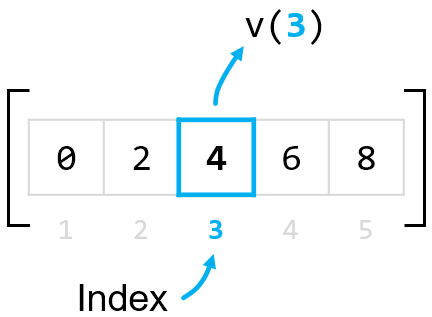

Use indexing to obtain the fifth element from the vector `v6` and store it in a variable named `x`.

x = v6(5)

x = 6.2832

### Vector Manipulation

Use an equal sign (=) after the indexing operation to assign new values to vector elements.

            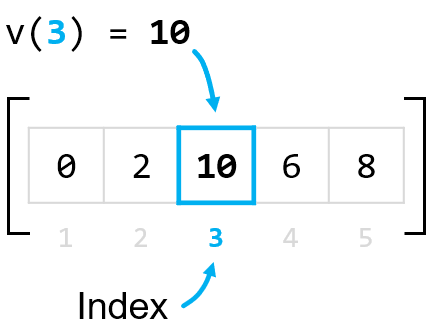

Change the third value of the v6 vector to 0.

v6(3) = 0

v6 =          0    1.5708         0    4.7124    6.2832


## Math Operations with Vectors

### Arithmetic Operations

Use elementwise operators to perform mathematical operations on the corresponding elements of two vectors. Below are examples of common math operators in MATLAB.

            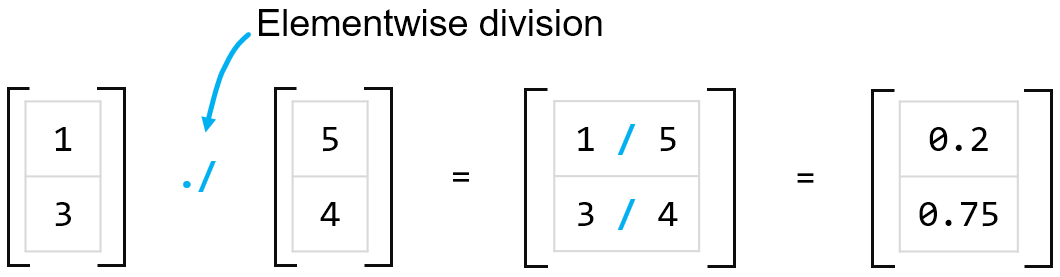

Given the vectors `A` and `B`, compute the elementwise multiplication of `A` times `B`. Store the result in a new vector named `C`.

A = [1; 28; 40];
B = [16; 35; 120];
C = A.*B

C =           16
         980
        4800


### Math Functions

There are many common mathematical functions in that operate on vectors. The function is automatically applied to every element of the vector.

               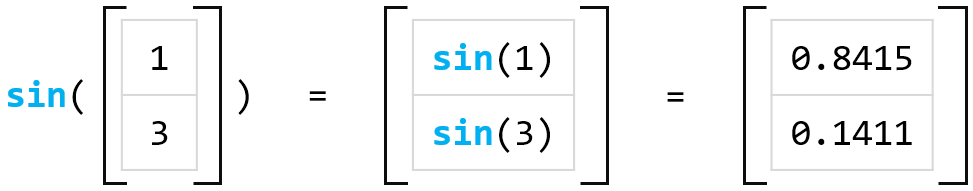

Given the vectors `expected` and `experimental` defined below, compute the percent error for each element using the equation below. 

            
$$\textrm{percent}\textrm{Error}=\textrm{abs}\left(\frac{\textrm{experimental}-\textrm{expected}}{\textrm{expected}}\right)\cdot \;100$$


Store the result in a new row vector named `percentError`. Use the [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html) function to compute the absolute value.

expected = [50 55 60 65 70 75];
experimental = [48.8 55.2 54 62.8 65.7 74.6];
percentError = abs(((experimental-expected)./expected).*100)

percentError =     2.4000    0.3636   10.0000    3.3846    6.1429    0.5333


The resulting row vector should have six unique values ranging from about 0.36 to 10.

## Vector Characteristics

### Transpose

You can use the transpose operator to transform a row vector into a column vector (or a column vector into a row vector). 

            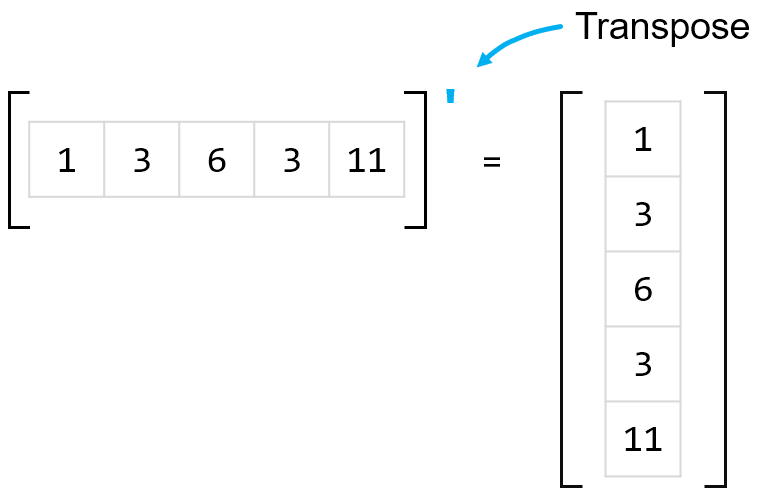

Transpose the `percentError` row vector calculated above into a column vector. Store the result in a new vector named `peCol`.

peCol = percentError'

peCol =     2.4000
    0.3636
   10.0000
    3.3846
    6.1429
    0.5333


### Size and Length

The [`size`](https://www.mathworks.com/help/matlab/ref/size.html) function returns the number of rows and the number of columns of a vector. The [`length`](https://www.mathworks.com/help/matlab/ref/length.html) function is similar but returns only the length of the longest dimension, regardless of whether it is a row or column vector.

            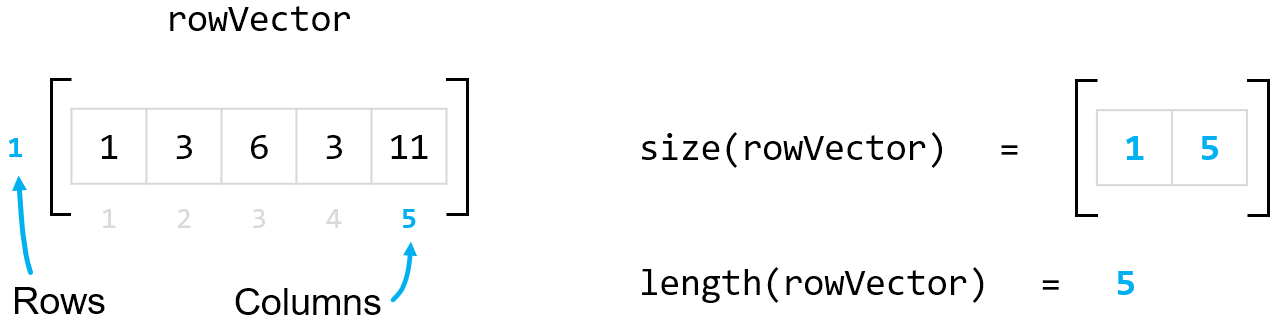

Use the `size` function to get the size (rows and columns) of the `peCol` vector. Use the `length` function to get the length of the `peCol` vector. Notice how the output of the `length` function differs from the `size` function.

size(peCol)

ans =      6     1


length(peCol)

ans = 6

## Conclusion

In this reading, you practiced some essential operations with vectors. You learned about creating vectors, accessing vector elements, manipulating vector data, and how to perform mathematical operations with vectors. You also learned how to convert between row and column vectors and get a vector's number of rows and/or columns.

The more you practice, the better you'll become at working with vectors. Feel free to use the space below to explore more operations with vectors.